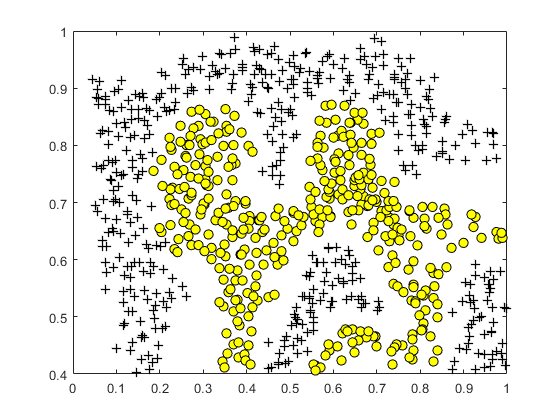

% Load X,y data 
clear all
close all
load('ex6data2.mat');

global kS D
kS = [0]; D=[0];

% Plot data
plotData(X, y); 


% SVM Parameters
C = 1; sigma = 0.0434;

tStart = cputime;
% Model optimization
model= svmTrain2(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma)); 


Training ............................................ Done! 



tEnd = cputime - tStart

tEnd = 2.3906

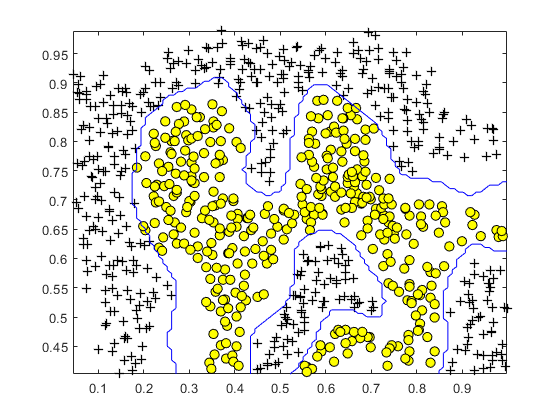


% Visualization
visualizeBoundary(X, y, model);


% Classification result
p = svmPredict(model, X);
fprintf('Classification Accuracy: %f\n', mean(double(p == y)) * 100);

Classification Accuracy: 99.652375


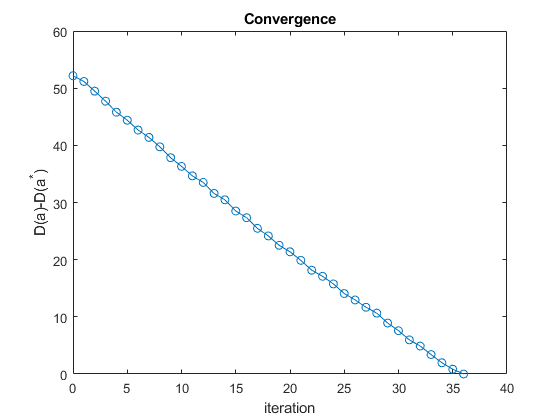


% Convergence
figure
plot(kS,D-D(end),'o-')
title('Convergence')
ylabel('D(a)-D(a^{*})')
xlabel('iteration')

corrcoef(kS,D)

ans =     1.0000   -0.9992
   -0.9992    1.0000


    
% Positive definite
V = eig(model.K);
sum(V>0) 

ans = 860

size(V)

ans =    863     1


%no degenerated
Q = model.Q;
a = model.a;
as2 = ((Q*a-1+y)==0).*(a==0 + a==C);
sum(as2) %number of degenerated values

ans = 0

% Co
mdl = fitlm(kS,D)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -0.80501     0.21289    -3.7814    0.00058469
    x1              -1.4692    0.010172    -144.43     3.527e-50


Number of observations: 37, Error degrees of freedom: 35
Root Mean Squared Error: 0.661
R-squared: 0.998,  Adjusted R-Squared: 0.998
F-statistic vs. constant model: 2.09e+04, p-value = 3.53e-50

% plot(mdl)

figure
idx = 1:length(D)-2;
Dp = D(idx) - D(end); %D(a^{p}) - D(a^{*})
Dp1 = D(idx+1) - D(end); %D(a^{p+1}) - D(a^{*})
ratio = Dp1 ./ Dp;
plot(idx, ratio,'o-')
hold

Current plot held


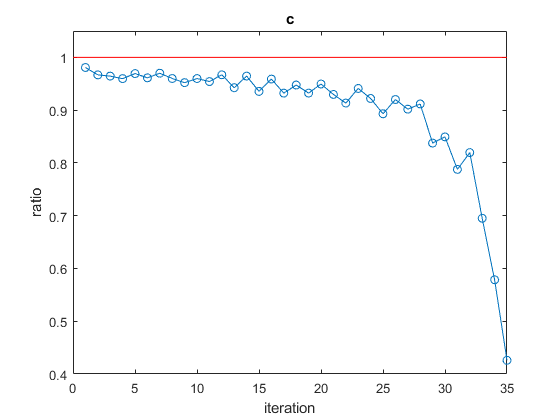

plot([0 idx(end)], [1 1],'r-')
title('c')
ylabel('ratio')
xlabel('iteration')
ylim([0.4 1.05])